# R2023b で markdown 変換できるようになった

export 関数（[LINK](https://jp.mathworks.com/help/matlab/ref/export.html?lang=en)）がついに livescript から markdown (Jupyter® notebook も）への変換が公式サポートされるようになりました。Doc は英語で表示しないと R2023b (最新版）の内容が表示されないので要注意です。

正確な仕様はドキュメントを確認するとしても、ちょっとややこしいので markdown 変換に絞って使い方例をまとめます。

- 使用環境：R2023b

これまでは自作の livescript2markdown 関数を使用していましたが、これを機に [export 関数](https://jp.mathworks.com/help/matlab/ref/export.html?lang=en)を使うようにしたいと思います。

参考：[【MATLAB】ライブスクリプトの Markdown 変換で楽して Qiita 投稿](https://qiita.com/eigs/items/513a17bd8cb2c5c5f435)

### 準備

変換後の markdown を確認するために画像やら数式を入れておきます。

#### 数式


$$\begin{array}{rl}
\frac{\partial {\bf u}}{\partial t} + {\bf u} \cdot \nabla {\bf u} &= - \nabla p + \frac{1}{Re} \nabla^2 {\bf u} \\
\nabla \cdot {\bf u} &= 0
\end{array}$$


#### 画像

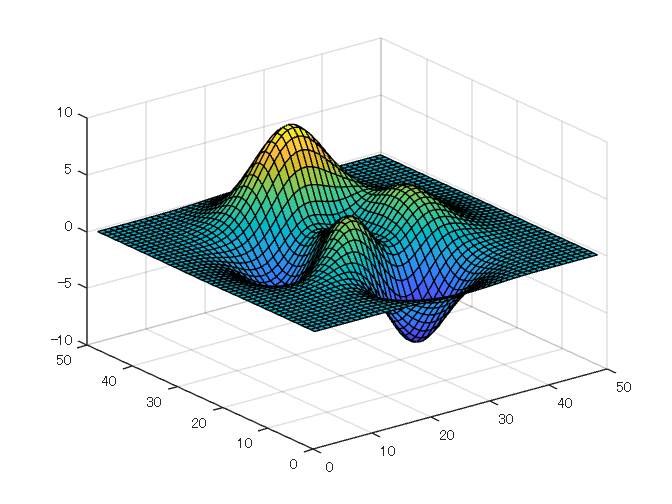

surf(peaks);

## デフォルトの動作

export("doc.mlx","doc_ver1.md");

結果はこちら：[doc_ver1.md](matlab:open('doc_ver1.md')) 

ファイルを見ると数式は

そして画像は

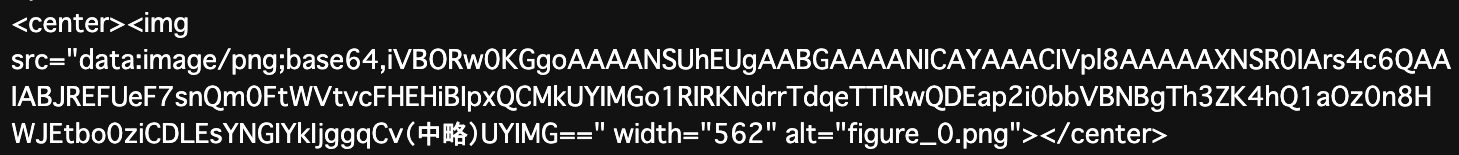

こんな感じ。画像が埋め込まれちゃってますね。画像等のファイルを出さずに markdown ファイル１つで済む点はメリットですが、画像ファイルも欲しい（個別に確認したい）場合は不便ですね。

ちなみに、

livescript 名と同じ markdown ファイルですとこんな実行方法でもOK.

## 画像ファイルも作る場合

画像ファイルを別途作成させる場合はこれ。`EmbedImages` オプションを設定します。

export("doc.mlx","doc_ver2.md",EmbedImages=false);

結果はこちら：[doc_ver2.md](matlab:open('doc_ver2.md')) 

今度は

と、画像ファイルを参照しています。

画像ファイルは (markdown ファイル名)_media のフォルダ内に保存されますね。今回のケースですと [`doc_ver2_media`](matlab:open('doc_ver2_media')) です。

ちなみに画像ファイル形式は FigureFormat から選べますが、`Run` オプションを `true` にし markdown 変換前に一度 livescript を実行させるようにしないといけない点に要注意。

選べる選択肢は以下の通り

`FigureFormat` **—** **Figure format**

`"png"` | `"jpeg"` | `"bmp"` | `"svg"` | `"eps"` | `"pdf"`

## 数式は画像で表示したい場合

少し前まで GitHub がそうでしたが、 latex がレンダリングされない環境だと数式は画像にして表示しましょう。`RenderLaTeXOnline` オプションです。`"svg"` | `"png"` | `"jpeg"` から選べますが、ここでは `"svg"` で行ってみます。

export("doc.mlx","doc_ver3.md",RenderLaTeXOnline='svg');

結果はこちら：[doc_ver3.md](matlab:open('doc_ver3.md')) 

数式部分は

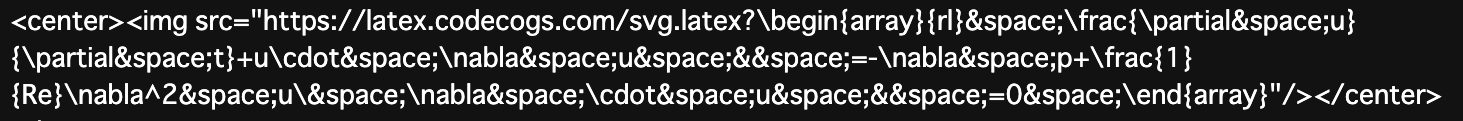

こんな感じで latex.codecogs.com のサービスを利用しています。

便利なのですがダークモードで表示すると見えない、見にくいなどの課題がある点は要注意です。

## その他使うかもしれないオプション

#### `IncludeOutputs` **—** `true` or `1` (default) | `false` or `0`

コードの出力結果を含めるかどうか。デフォルトでは `true` になってます。

#### `Run` **—** `false` or `0` (default) | `true` or `1`

変換前に一度コードを実行するかどうか。デフォルトでは false になってます。まだ実行していない livescript で出力が欲しい場合は実行した方がいいですね。

#### `HideCode` **— **`true` or `1` | `false` or `0`

コードを隠しての出力。基本的に livescript 側の設定（表示・非表示）に従いますが、このオプションで指定可能。

#### `AcceptHTML` **—** `true` or `1` (default) | `false` or `0`

細かい色の設定（タイトル）や挿入した画像のサイズなどしっかり markdown にも反映させたい場合に必要。ただ表示側の環境に依存します。

#### `FigureResolution` **—** `600` (default) | positive integer

画像の解像度設定ですね。

## まとめ

以上！基本的なところだけですが簡単に紹介いたしました。

export("doc.mlx","README.md",EmbedImages=false);

でこの repo の README としておきます。

個人的には、[【MATLAB】ライブスクリプトの Markdown 変換で楽して Qiita 投稿](https://qiita.com/eigs/items/513a17bd8cb2c5c5f435) で紹介した関数・コードが製品に（開発チームの大幅な修正・慎重な検証ののち）採用されたということで思い入れの強い関数 [export](https://jp.mathworks.com/help/matlab/ref/export.html?lang=en) でした。